n=10;
[bestindv,bestresult,Results,meanGAesVar,stdGAesVar,BestHistory,CurrentHistory,Step,FitnessOnValidation]...
    = fGAmultiLineBest(10,n,40,50,15,9,5,3,TR_DATA,VA_DATA);

stopped eary on iter:
    22

stopped eary on iter:
    23

stopped eary on iter:
    11

stopped eary on iter:
    11

stopped eary on iter:
    21

stopped eary on iter:
    29



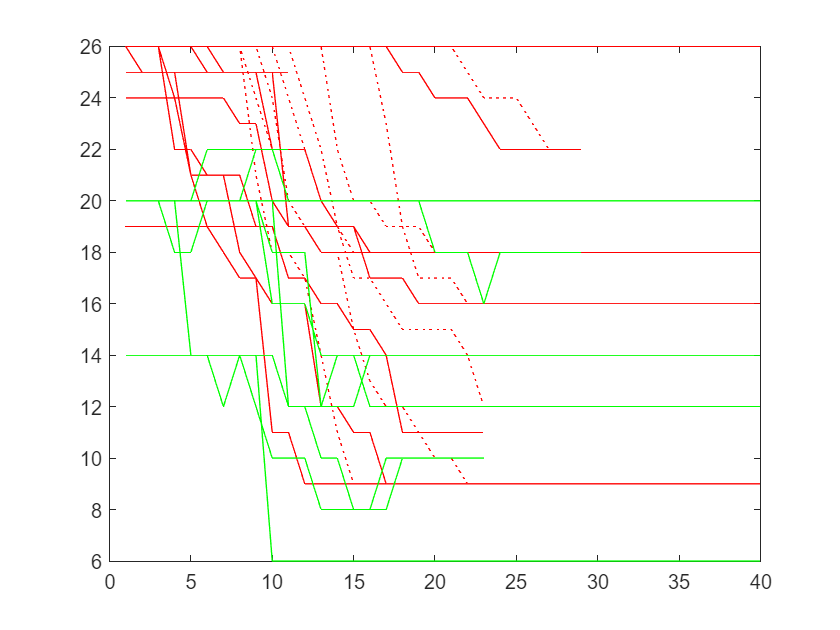


xlabel('Iteration number');
    ylabel('Objective function value');
for i=1:n

 plot(BestHistory(i,:),'Color','r'); hold on      
   plot(CurrentHistory(i,:),'Color','r','LineStyle',':'); 
   
    
end
for i=1:n
plot(FitnessOnValidation(i,:)*2,'g')
end
hold off;

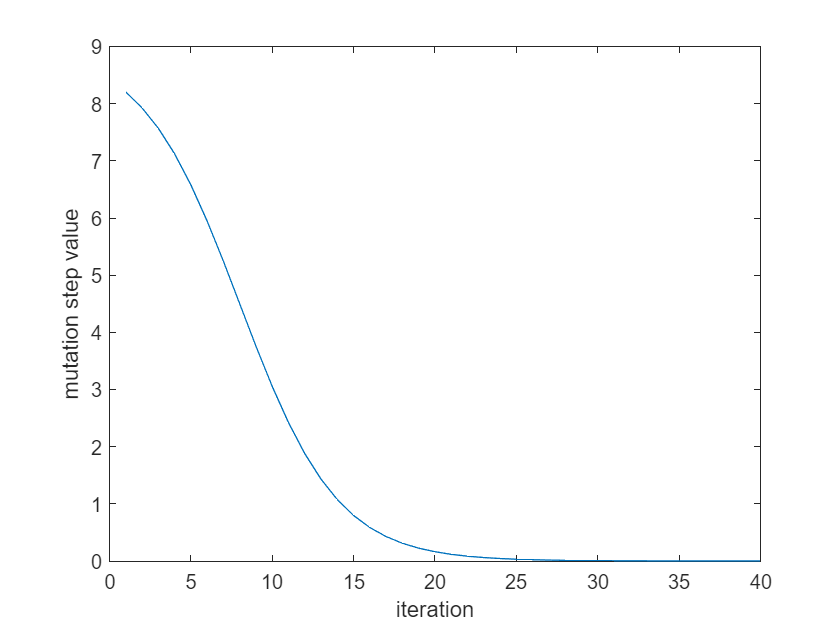

plot(Step(1,:))
xlabel('iteration');
ylabel('mutation step value');


disp('best indv cost>>');disp(bestresult);

best indv cost>>
   NaN



disp('results>>');disp(bestindv)

results>>
  1×10 struct array with fields:

    OF
    Parameters



c=zeros(n,1);
parfor i=1:n
    c(i,1)=fcost(bestindv(i).Parameters.W1,bestindv(i).Parameters.W2,bestindv(i).Parameters.B,VA_DATA);
end
disp(c);

     3
     4
    10
     7
     4
     9
     6
    10
     6
     8



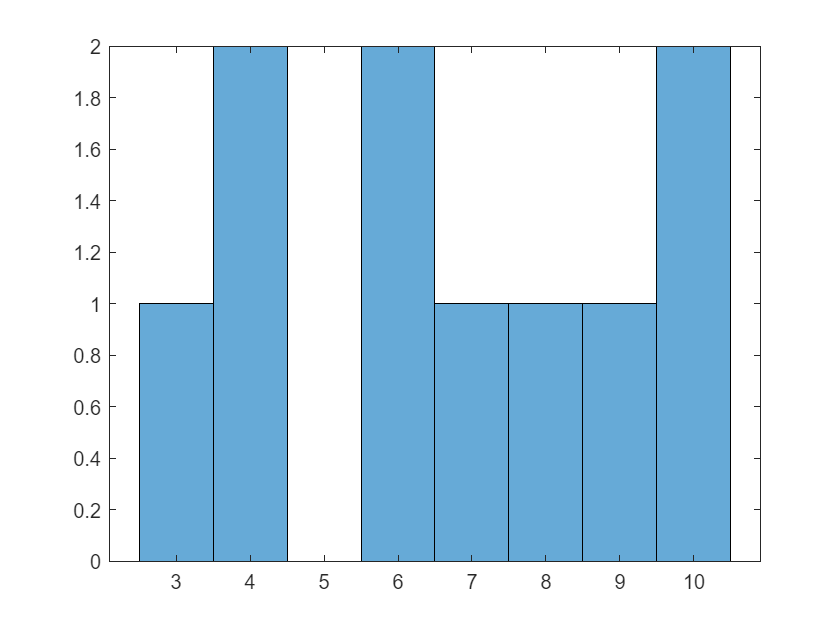

histogram(c)